Aufgabe 3)

4.

clear;
Td = 0.1;
Fs = 50000;
n = 0 : Td * Fs - 1;
t = n / Fs;
N = 5000;

f1 = 30;
f2 = 100;
f3 = 200;

x = cos(2*pi*f1*t) + sin(2*pi*f2*t) + 2*cos(2*pi*f3*t+(pi/2));
X = fft(x);
counter = 0;
for i = 1 : length(X)
    if abs(X(1,i)) > 10e-10
        counter = counter + 1;
    end
end
disp(counter);

     6



7.

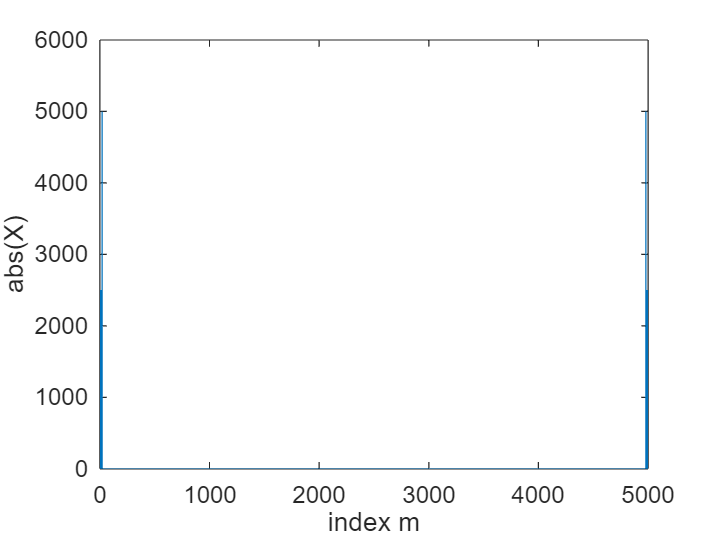

figure;
plot(n, abs(X));
xlabel("index m");
ylabel("abs(X)");

8.

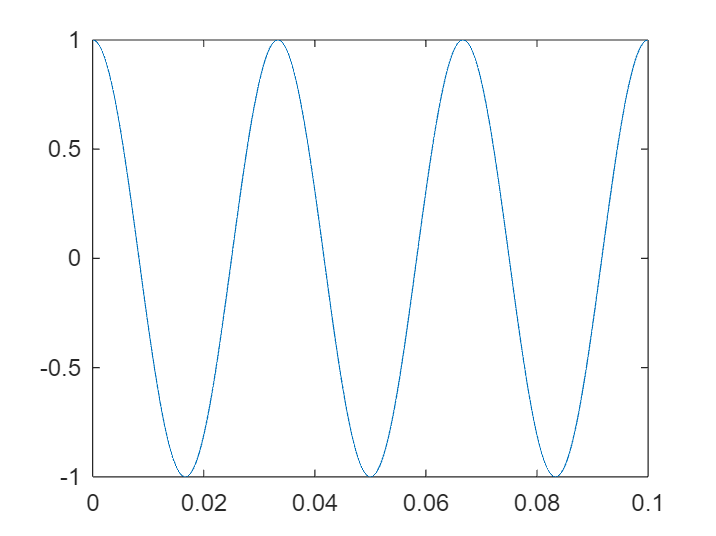

m1 = 3;
x1 = (1 / (N/2)) * X(1,m1 + 1) * exp(1i*2*pi*m1*n/N);

figure;
plot(t, cos(2*pi*f1*t));


figure;
plot(t, real(x1));

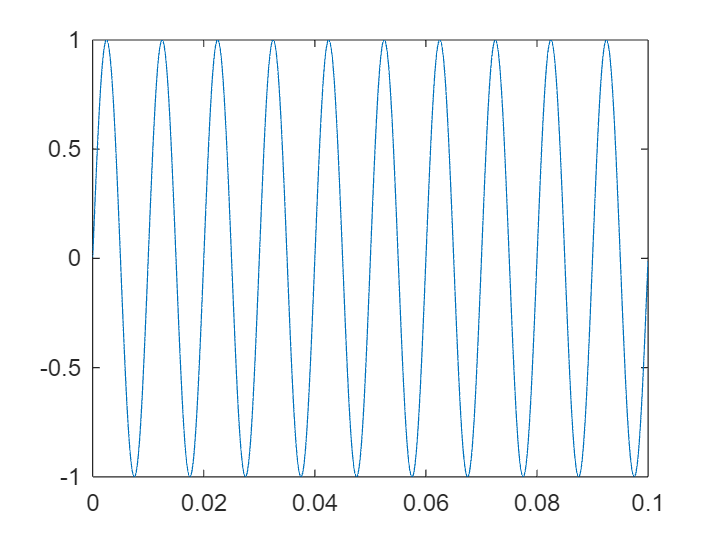


m2 = 10;
x2 = (1 / (N/2)) * X(1,m2 + 1) * exp(1i*2*pi*m2*n/N);

figure;
plot(t, sin(2*pi*f2*t));


figure;
plot(t, real(x2));

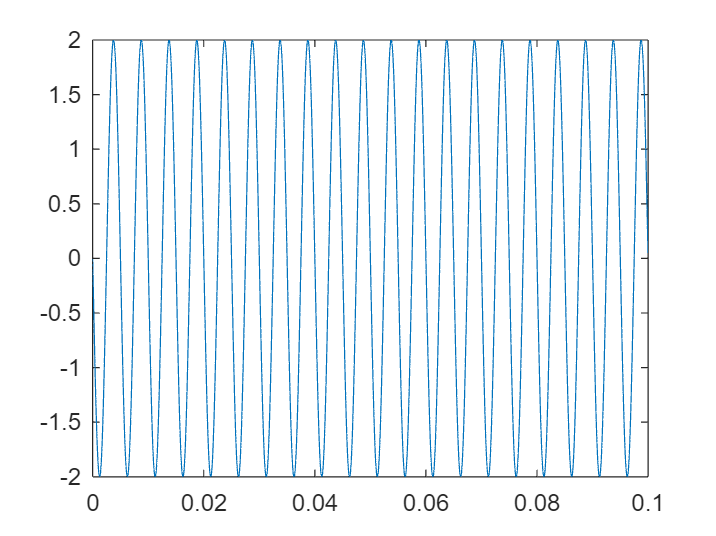


m3 = 20;
x3 = (1 / (N/2)) * X(1,m3 + 1) * exp(1i*2*pi*m3*n/N);

figure;
plot(t, 2*cos(2*pi*f3*t + (pi/2)));


figure;
plot(t, real(x3));